# Robot PKM

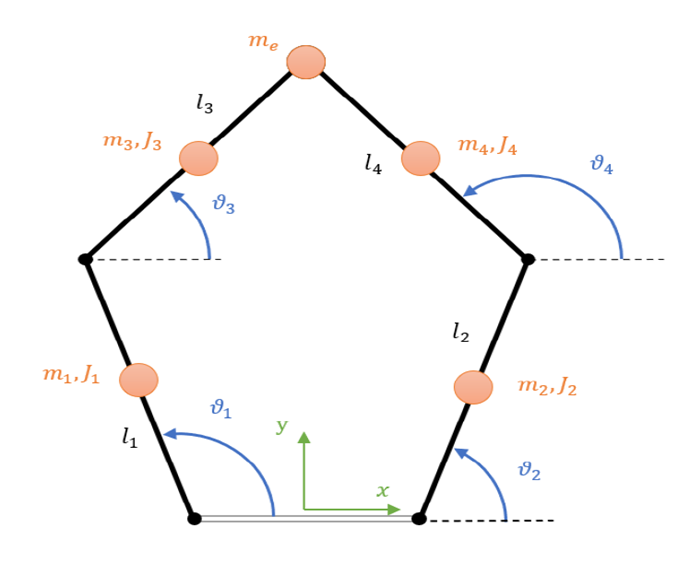

##   Definizione dati e informazioni utili manipolatore 

[PKM] = Define_Robot();

% Definizione parametri di test
theta1 = deg2rad(120); % Condizione iniziale posizione Theta1
theta2 = deg2rad(60); %  Condizione iniziale posizione Theta2
thetaV = deg2rad(720); % Angolo proprio della vite

theta1_p = 0; %  Condizione iniziale velocità theta1
theta2_p = 0; %  Condizione iniziale velocità tehta2
thetaV_p = 0; % Velocita thetav di prova

theta1_pp = 0; %  Condizione iniziale accelerazione theta1
theta2_pp = 0; %  Condizione iniziale accelarazione theta2
thetaV_pp = 0; % Accelerazione thetav di prova

## Legge di moto

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


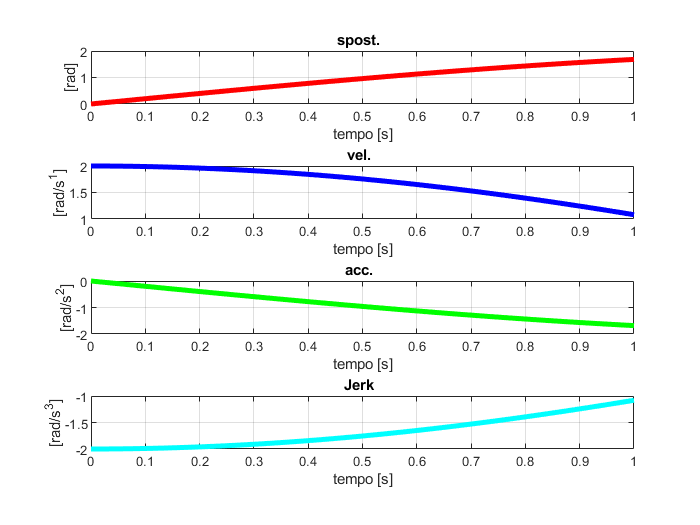

Ldm_theta1 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta1] = Define_ldm(2, 'Sin') % Definisce una legge di moto data l'alzata in gradi per theta1

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


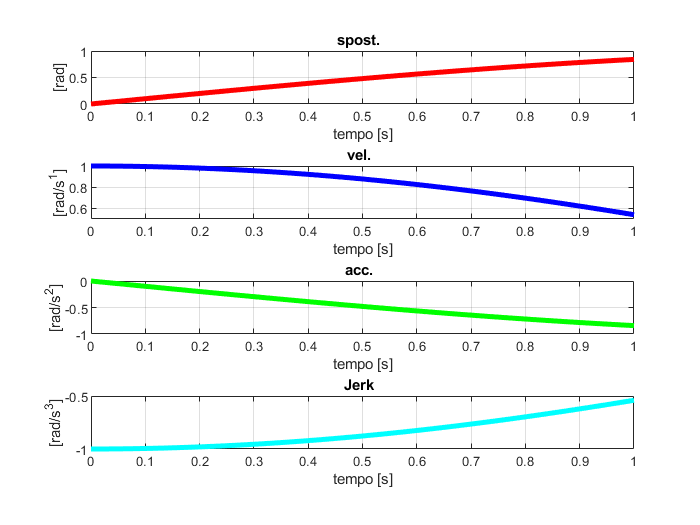

Ldm_theta2 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta2] = Define_ldm(1, 'Sin') % Definisce una legge di moto data l'alzata in gradi per theta2

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


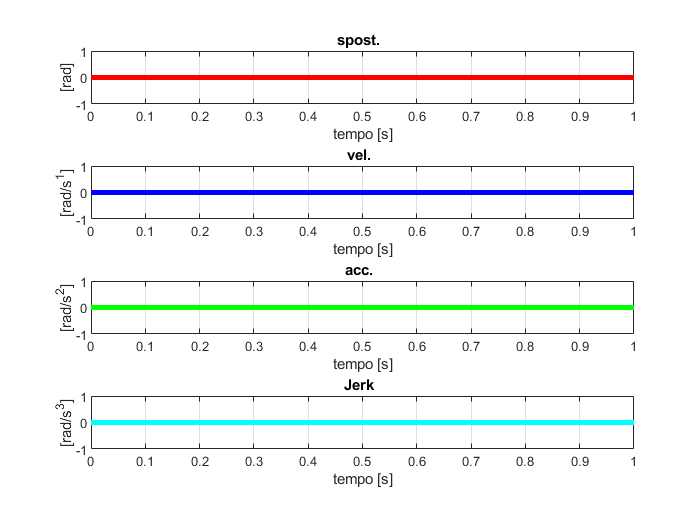

Ldm_thetav = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_thetav] = Define_ldm(0, 'pol357') % Definisce una legge di moto per la vite


theta1ldm = theta1 + Ldm_theta1.moto.data{1,1}.v;
theta2ldm = theta2 + Ldm_theta2.moto.data{1,1}.v;
thetavldm = thetaV + Ldm_thetav.moto.data{1,1}.v;
PKM.ta = Ldm_theta1.vldm{1,1}.ta+Ldm_theta1.vldm{1,2}.ta+Ldm_theta1.vldm{1,3}.ta+Ldm_theta1.vldm{1,4}.ta;

Theta = [theta1ldm; theta2ldm; thetavldm]

Theta =     2.0944    2.0964    2.0984    2.1004    2.1024    2.1044    2.1064    2.1084    2.1104    2.1124    2.1144    2.1164    2.1184    2.1204    2.1224    2.1244    2.1264    2.1284    2.1304    2.1324    2.1344    2.1364    2.1384    2.1404    2.1424    2.1444    2.1464    2.1484    2.1504    2.1524    2.1544    2.1564    2.1584    2.1604    2.1625    2.1645    2.1665    2.1685    2.1705    2.1725    2.1745    2.1765    2.1785    2.1805    2.1825    2.1845    2.1865    2.1885    2.1905    2.1925
    1.0472    1.0482    1.0492    1.0502    1.0512    1.0522    1.0532    1.0542    1.0552    1.0562    1.0572    1.0582    1.0592    1.0602    1.0612    1.0622    1.0632    1.0642    1.0652    1.0662    1.0672    1.0682    1.0692    1.0702    1.0712    1.0722    1.0732    1.0742    1.0752    1.0762    1.0772    1.0782    1.0792    1.0802    1.0812    1.0822    1.0832    1.0842    1.0852    1.0862    1.0872    1.0882    1.0892    1.0902    1.0912    1.0922    1.0932    1.0942    1.0952 

## Cinematica diretta

**Analisi di posizione**

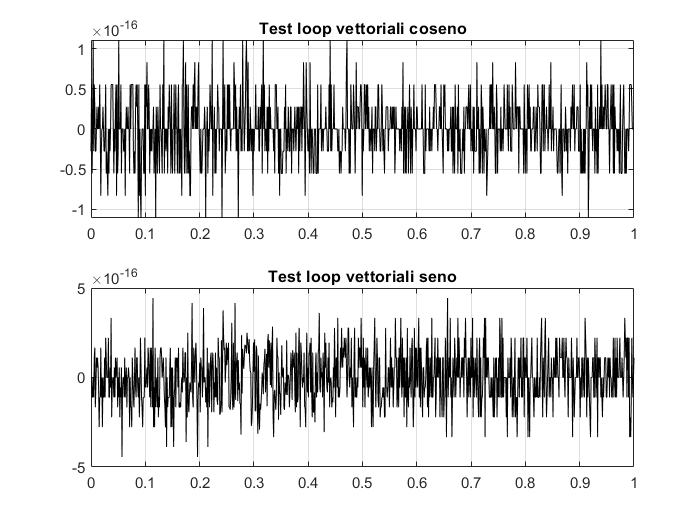

P =     0.0000   -0.0004   -0.0009   -0.0013   -0.0017   -0.0022   -0.0026   -0.0030   -0.0035   -0.0039   -0.0043   -0.0048   -0.0052   -0.0056   -0.0061   -0.0065   -0.0069   -0.0074   -0.0078   -0.0082   -0.0086   -0.0091   -0.0095   -0.0099   -0.0103   -0.0108   -0.0112   -0.0116   -0.0120   -0.0125   -0.0129   -0.0133   -0.0137   -0.0142   -0.0146   -0.0150   -0.0154   -0.0158   -0.0163   -0.0167   -0.0171   -0.0175   -0.0179   -0.0183   -0.0188   -0.0192   -0.0196   -0.0200   -0.0204   -0.0208
    0.3441    0.3438    0.3436    0.3433    0.3431    0.3428    0.3426    0.3423    0.3421    0.3418    0.3416    0.3413    0.3411    0.3408    0.3406    0.3403    0.3401    0.3398    0.3395    0.3393    0.3390    0.3388    0.3385    0.3382    0.3380    0.3377    0.3375    0.3372    0.3369    0.3367    0.3364    0.3361    0.3359    0.3356    0.3353    0.3351    0.3348    0.3345    0.3342    0.3340    0.3337    0.3334    0.3331    0.3329    0.3326    0.3323    0.3320    0.3318    0.3315    0

theta3 =     0.5355    0.5356    0.5356    0.5356    0.5356    0.5357    0.5357    0.5357    0.5357    0.5358    0.5358    0.5358    0.5359    0.5359    0.5359    0.5359    0.5360    0.5360    0.5360    0.5361    0.5361    0.5361    0.5362    0.5362    0.5363    0.5363    0.5363    0.5364    0.5364    0.5365    0.5365    0.5365    0.5366    0.5366    0.5367    0.5367    0.5368    0.5368    0.5368    0.5369    0.5369    0.5370    0.5370    0.5371    0.5371    0.5372    0.5372    0.5373    0.5373    0.5374


theta4 =     2.6061    2.6078    2.6095    2.6112    2.6130    2.6147    2.6164    2.6181    2.6199    2.6216    2.6233    2.6251    2.6268    2.6285    2.6302    2.6320    2.6337    2.6354    2.6372    2.6389    2.6406    2.6424    2.6441    2.6459    2.6476    2.6493    2.6511    2.6528    2.6545    2.6563    2.6580    2.6598    2.6615    2.6633    2.6650    2.6667    2.6685    2.6702    2.6720    2.6737    2.6755    2.6772    2.6790    2.6807    2.6825    2.6842    2.6860    2.6877    2.6895    2.6912


E1 =    -0.2150   -0.2154   -0.2159   -0.2163   -0.2167   -0.2172   -0.2176   -0.2180   -0.2185   -0.2189   -0.2193   -0.2197   -0.2202   -0.2206   -0.2210   -0.2214   -0.2219   -0.2223   -0.2227   -0.2231   -0.2236   -0.2240   -0.2244   -0.2248   -0.2253   -0.2257   -0.2261   -0.2265   -0.2269   -0.2274   -0.2278   -0.2282   -0.2286   -0.2290   -0.2294   -0.2298   -0.2303   -0.2307   -0.2311   -0.2315   -0.2319   -0.2323   -0.2327   -0.2331   -0.2336   -0.2340   -0.2344   -0.2348   -0.2352   -0.2356
    0.2165    0.2163    0.2160    0.2158    0.2155    0.2152    0.2150    0.2147    0.2145    0.2142    0.2140    0.2137    0.2134    0.2132    0.2129    0.2127    0.2124    0.2121    0.2119    0.2116    0.2113    0.2111    0.2108    0.2105    0.2103    0.2100    0.2097    0.2094    0.2092    0.2089    0.2086    0.2083    0.2081    0.2078    0.2075    0.2072    0.2069    0.2067    0.2064    0.2061    0.2058    0.2055    0.2052    0.2050    0.2047    0.2044    0.2041    0.2038    0.2035    

E2 =     0.2150    0.2148    0.2146    0.2143    0.2141    0.2139    0.2137    0.2135    0.2133    0.2130    0.2128    0.2126    0.2124    0.2122    0.2120    0.2117    0.2115    0.2113    0.2111    0.2109    0.2106    0.2104    0.2102    0.2100    0.2098    0.2095    0.2093    0.2091    0.2089    0.2087    0.2084    0.2082    0.2080    0.2078    0.2076    0.2073    0.2071    0.2069    0.2067    0.2065    0.2062    0.2060    0.2058    0.2056    0.2053    0.2051    0.2049    0.2047    0.2045    0.2042
    0.2165    0.2166    0.2168    0.2169    0.2170    0.2171    0.2173    0.2174    0.2175    0.2176    0.2177    0.2179    0.2180    0.2181    0.2182    0.2184    0.2185    0.2186    0.2187    0.2188    0.2190    0.2191    0.2192    0.2193    0.2194    0.2196    0.2197    0.2198    0.2199    0.2200    0.2202    0.2203    0.2204    0.2205    0.2206    0.2208    0.2209    0.2210    0.2211    0.2212    0.2213    0.2215    0.2216    0.2217    0.2218    0.2219    0.2220    0.2221    0.2223    

[P, theta3, theta4, E1, E2] = Cinematica_Diretta_Posizione(PKM, theta1ldm, theta2ldm, thetavldm)

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1ldm,theta2ldm,theta3,theta4)

**Analisi di velocità**

theta1ldm_p = theta1_p + Ldm_theta1.moto.data{2,1}.v;
theta2ldm_p = theta2_p + Ldm_theta2.moto.data{2,1}.v;
thetavldm_p = thetaV_p + Ldm_thetav.moto.data{2,1}.v;

[P_p, J, P_pM] = Cinematica_Diretta_Velocita2(PKM, theta1ldm, theta2ldm, theta1ldm_p,theta2ldm_p,thetavldm_p,P)

P_p =    -0.4360   -0.4356   -0.4352   -0.4347   -0.4343   -0.4339   -0.4334   -0.4330   -0.4325   -0.4321   -0.4316   -0.4312   -0.4307   -0.4303   -0.4298   -0.4294   -0.4289   -0.4285   -0.4280   -0.4275   -0.4271   -0.4266   -0.4261   -0.4256   -0.4252   -0.4247   -0.4242   -0.4237   -0.4232   -0.4227   -0.4223   -0.4218   -0.4213   -0.4208   -0.4203   -0.4198   -0.4193   -0.4188   -0.4183   -0.4178   -0.4172   -0.4167   -0.4162   -0.4157   -0.4152   -0.4147   -0.4141   -0.4136   -0.4131   -0.4126
   -0.2449   -0.2457   -0.2464   -0.2472   -0.2479   -0.2486   -0.2494   -0.2501   -0.2508   -0.2516   -0.2523   -0.2530   -0.2537   -0.2545   -0.2552   -0.2559   -0.2566   -0.2574   -0.2581   -0.2588   -0.2595   -0.2602   -0.2610   -0.2617   -0.2624   -0.2631   -0.2638   -0.2645   -0.2652   -0.2659   -0.2666   -0.2673   -0.2680   -0.2687   -0.2694   -0.2701   -0.2708   -0.2715   -0.2722   -0.2729   -0.2736   -0.2743   -0.2750   -0.2757   -0.2764   -0.2771   -0.2777   -0.2784   -0.2791   

J =    -0.1453   -0.1453         0   -0.1451   -0.1455         0   -0.1448   -0.1456         0   -0.1445   -0.1458         0   -0.1442   -0.1459         0   -0.1439   -0.1461         0   -0.1436   -0.1462         0   -0.1433   -0.1464         0   -0.1430   -0.1465         0   -0.1427   -0.1466         0   -0.1424   -0.1468         0   -0.1421   -0.1469         0   -0.1418   -0.1471         0   -0.1415   -0.1472         0   -0.1412   -0.1474         0   -0.1409   -0.1476         0   -0.1406   -0.1477
   -0.2449    0.2449         0   -0.2454    0.2452         0   -0.2459    0.2454         0   -0.2464    0.2456         0   -0.2469    0.2459         0   -0.2474    0.2461         0   -0.2478    0.2463         0   -0.2483    0.2465         0   -0.2488    0.2468         0   -0.2493    0.2470         0   -0.2498    0.2472         0   -0.2503    0.2475         0   -0.2507    0.2477         0   -0.2512    0.2480         0   -0.2517    0.2482         0   -0.2522    0.2484         0   -0.2527    0

P_pM =    -0.4358   -0.4354   -0.4349   -0.4345   -0.4341   -0.4336   -0.4332   -0.4328   -0.4323   -0.4319   -0.4314   -0.4310   -0.4305   -0.4301   -0.4296   -0.4292   -0.4287   -0.4282   -0.4278   -0.4273   -0.4268   -0.4264   -0.4259   -0.4254   -0.4249   -0.4244   -0.4240   -0.4235   -0.4230   -0.4225   -0.4220   -0.4215   -0.4210   -0.4205   -0.4200   -0.4195   -0.4190   -0.4185   -0.4180   -0.4175   -0.4170   -0.4165   -0.4160   -0.4154   -0.4149   -0.4144   -0.4139   -0.4133   -0.4128   -0.4123


Theta_p = [theta1ldm_p;theta2ldm_p;thetavldm_p]

Theta_p =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    1.9999    1.9999    1.9999    1.9999    1.9999    1.9998    1.9998    1.9998    1.9997    1.9997    1.9997    1.9996    1.9996    1.9996    1.9995    1.9995    1.9994    1.9994    1.9993    1.9993    1.9992    1.9992    1.9991    1.9990    1.9990    1.9989    1.9988    1.9988    1.9987    1.9986    1.9986    1.9985    1.9984    1.9983    1.9982    1.9981    1.9981    1.9980    1.9979    1.9978    1.9977    1.9976
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9997    0.9996    0.9996    0.9996    0.9995    0.9995    0.9995    0.9995    0.9994    0.9994    0.9994    0.9993    0.9993    0.9992    0.9992    0.9992    0.9991    0.9991    0.9990    0.9990    0.9989    0.9989    0.998

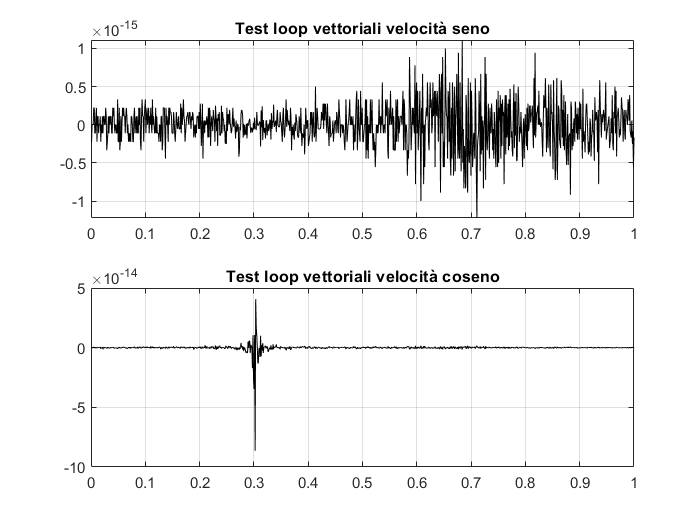

theta3_p =     0.0235    0.0241    0.0247    0.0253    0.0259    0.0265    0.0270    0.0276    0.0282    0.0288    0.0294    0.0300    0.0305    0.0311    0.0317    0.0323    0.0328    0.0334    0.0340    0.0346    0.0351    0.0357    0.0363    0.0369    0.0374    0.0380    0.0386    0.0391    0.0397    0.0403    0.0408    0.0414    0.0420    0.0425    0.0431    0.0437    0.0442    0.0448    0.0454    0.0459    0.0465    0.0470    0.0476    0.0481    0.0487    0.0493    0.0498    0.0504    0.0509    0.0515


theta4_p =     1.7206    1.7213    1.7220    1.7227    1.7233    1.7240    1.7247    1.7253    1.7260    1.7266    1.7273    1.7279    1.7286    1.7292    1.7298    1.7305    1.7311    1.7317    1.7323    1.7330    1.7336    1.7342    1.7348    1.7354    1.7360    1.7366    1.7372    1.7378    1.7384    1.7390    1.7396    1.7401    1.7407    1.7413    1.7419    1.7424    1.7430    1.7436    1.7441    1.7447    1.7452    1.7458    1.7463    1.7469    1.7474    1.7479    1.7485    1.7490    1.7495    1.7501


J34 =    -0.5579    1.1393   -0.5581    1.1403   -0.5583    1.1414   -0.5586    1.1425   -0.5588    1.1436   -0.5591    1.1446   -0.5593    1.1457   -0.5596    1.1468   -0.5599    1.1479   -0.5601    1.1490   -0.5604    1.1502   -0.5607    1.1513   -0.5609    1.1524   -0.5612    1.1535   -0.5615    1.1547   -0.5618    1.1558   -0.5620    1.1569   -0.5623    1.1581   -0.5626    1.1592   -0.5629    1.1604   -0.5632    1.1616   -0.5635    1.1627   -0.5638    1.1639   -0.5641    1.1651   -0.5644    1.1663
    1.1393   -0.5579    1.1403   -0.5593    1.1414   -0.5608    1.1425   -0.5623    1.1436   -0.5638    1.1447   -0.5653    1.1458   -0.5668    1.1469   -0.5684    1.1480   -0.5699    1.1490   -0.5714    1.1501   -0.5729    1.1512   -0.5744    1.1523   -0.5760    1.1534   -0.5775    1.1545   -0.5790    1.1556   -0.5806    1.1567   -0.5821    1.1578   -0.5837    1.1589   -0.5852    1.1600   -0.5868    1.1611   -0.5883    1.1622   -0.5899    1.1633   -0.5914    1.1644   -0.5930    1.1655   

[theta3_p,theta4_p,J34] = Theta34p(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p)

**Analisi di accelerazione**

theta1ldm_pp = theta1_p + Ldm_theta1.moto.data{3,1}.v;
theta2ldm_pp = theta2_p + Ldm_theta2.moto.data{3,1}.v;
thetavldm_pp = thetaV_p + Ldm_thetav.moto.data{3,1}.v;

Theta_pp = [theta1ldm_pp;theta2ldm_pp;thetavldm_pp]

Theta_pp =          0   -0.0020   -0.0040   -0.0060   -0.0080   -0.0100   -0.0120   -0.0140   -0.0160   -0.0180   -0.0200   -0.0220   -0.0240   -0.0260   -0.0280   -0.0300   -0.0320   -0.0340   -0.0360   -0.0380   -0.0400   -0.0420   -0.0440   -0.0460   -0.0480   -0.0500   -0.0520   -0.0540   -0.0560   -0.0580   -0.0601   -0.0621   -0.0641   -0.0661   -0.0681   -0.0701   -0.0721   -0.0741   -0.0761   -0.0781   -0.0801   -0.0821   -0.0841   -0.0861   -0.0881   -0.0901   -0.0921   -0.0941   -0.0961   -0.0981
         0   -0.0010   -0.0020   -0.0030   -0.0040   -0.0050   -0.0060   -0.0070   -0.0080   -0.0090   -0.0100   -0.0110   -0.0120   -0.0130   -0.0140   -0.0150   -0.0160   -0.0170   -0.0180   -0.0190   -0.0200   -0.0210   -0.0220   -0.0230   -0.0240   -0.0250   -0.0260   -0.0270   -0.0280   -0.0290   -0.0300   -0.0310   -0.0320   -0.0330   -0.0340   -0.0350   -0.0360   -0.0370   -0.0380   -0.0390   -0.0400   -0.0410   -0.0420   -0.0430   -0.0440   -0.0450   -0.0460   -0.0470   -0.04

[P_pp] = Cinematica_Diretta_Accelerazione2(PKM,Theta, Theta_p, Theta_pp, P, P_p)

P_pp =     0.4250    0.4273    0.4295    0.4318    0.4340    0.4362    0.4385    0.4407    0.4429    0.4451    0.4473    0.4495    0.4517    0.4539    0.4561    0.4583    0.4604    0.4626    0.4648    0.4670    0.4691    0.4713    0.4734    0.4756    0.4777    0.4798    0.4820    0.4841    0.4862    0.4883    0.4904    0.4925    0.4946    0.4967    0.4988    0.5009    0.5030    0.5050    0.5071    0.5092    0.5112    0.5133    0.5153    0.5174    0.5194    0.5214    0.5235    0.5255    0.5275    0.5295
   -0.7400   -0.7389   -0.7378   -0.7367   -0.7355   -0.7344   -0.7333   -0.7321   -0.7310   -0.7298   -0.7287   -0.7275   -0.7263   -0.7252   -0.7240   -0.7228   -0.7216   -0.7204   -0.7192   -0.7179   -0.7167   -0.7155   -0.7142   -0.7130   -0.7117   -0.7104   -0.7092   -0.7079   -0.7066   -0.7053   -0.7040   -0.7027   -0.7014   -0.7001   -0.6988   -0.6974   -0.6961   -0.6948   -0.6934   -0.6921   -0.6907   -0.6893   -0.6879   -0.6866   -0.6852   -0.6838   -0.6824   -0.6810   -0.6796  

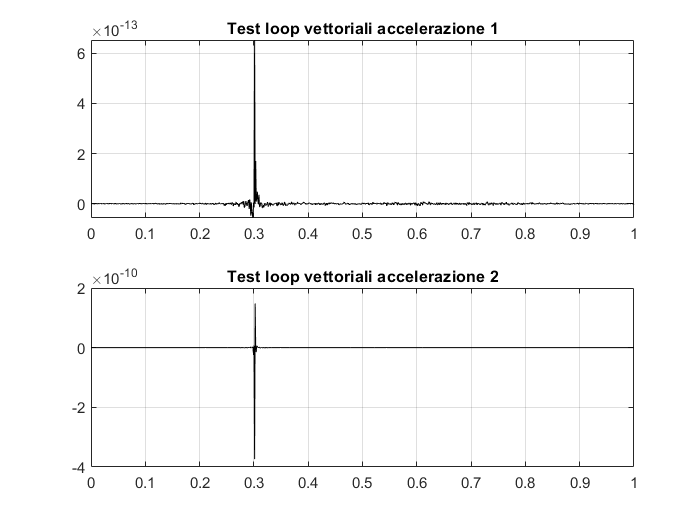

theta3_pp =     0.5866    0.5859    0.5852    0.5845    0.5838    0.5831    0.5824    0.5817    0.5810    0.5803    0.5796    0.5789    0.5782    0.5775    0.5768    0.5761    0.5754    0.5748    0.5741    0.5734    0.5727    0.5720    0.5714    0.5707    0.5700    0.5693    0.5687    0.5680    0.5673    0.5666    0.5660    0.5653    0.5646    0.5640    0.5633    0.5627    0.5620    0.5613    0.5607    0.5600    0.5594    0.5587    0.5581    0.5574    0.5568    0.5562    0.5555    0.5549    0.5542    0.5536


theta4_pp =     0.6780    0.6748    0.6715    0.6683    0.6651    0.6619    0.6586    0.6554    0.6522    0.6490    0.6458    0.6426    0.6394    0.6361    0.6329    0.6297    0.6265    0.6233    0.6201    0.6169    0.6137    0.6105    0.6073    0.6041    0.6009    0.5978    0.5946    0.5914    0.5882    0.5850    0.5818    0.5786    0.5755    0.5723    0.5691    0.5659    0.5627    0.5596    0.5564    0.5532    0.5500    0.5469    0.5437    0.5405    0.5374    0.5342    0.5310    0.5279    0.5247    0.5216


J34p =    -0.2394    1.0654   -0.2421    1.0701   -0.2448    1.0749   -0.2475    1.0797   -0.2503    1.0845   -0.2530    1.0893   -0.2558    1.0941   -0.2585    1.0990   -0.2613    1.1038   -0.2641    1.1087   -0.2668    1.1136   -0.2696    1.1185   -0.2724    1.1234   -0.2752    1.1284   -0.2780    1.1334   -0.2808    1.1384   -0.2837    1.1434   -0.2865    1.1484   -0.2893    1.1534   -0.2922    1.1585   -0.2950    1.1636   -0.2979    1.1687   -0.3008    1.1738   -0.3036    1.1789   -0.3065    1.1841
    1.0825   -1.4869    1.0833   -1.4902    1.0843   -1.4935    1.0852   -1.4969    1.0861   -1.5002    1.0870   -1.5036    1.0880   -1.5070    1.0890   -1.5104    1.0899   -1.5138    1.0909   -1.5173    1.0919   -1.5207    1.0929   -1.5242    1.0940   -1.5277    1.0950   -1.5313    1.0960   -1.5348    1.0971   -1.5384    1.0982   -1.5420    1.0993   -1.5456    1.1004   -1.5493    1.1015   -1.5529    1.1026   -1.5566    1.1037   -1.5603    1.1049   -1.5641    1.1060   -1.5678    1.1072  

[theta3_pp,theta4_pp,J34p] = Theta34pp(theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,...
    theta3_p,theta4_p,theta1ldm_pp, theta2ldm_pp,J34)


[C1_p, C2_p, C1_pp, C2_pp, E1_p, E1_pp, J1, J1p, J2, J2p, J3, J3p, J4, J4p, JE, JEp,P_p34, P_pp34] = Jacobiani(PKM, Theta, Theta_p, theta3, theta4, theta3_p, theta4_p, J34, J34p, P_pp, Theta_pp)

C1_p =    -0.2165   -0.2163   -0.2160   -0.2158   -0.2155   -0.2152   -0.2150   -0.2147   -0.2145   -0.2142   -0.2139   -0.2137   -0.2134   -0.2132   -0.2129   -0.2126   -0.2124   -0.2121   -0.2118   -0.2116   -0.2113   -0.2110   -0.2107   -0.2105   -0.2102   -0.2099   -0.2096   -0.2094   -0.2091   -0.2088   -0.2085   -0.2082   -0.2080   -0.2077   -0.2074   -0.2071   -0.2068   -0.2065   -0.2062   -0.2059   -0.2057   -0.2054   -0.2051   -0.2048   -0.2045   -0.2042   -0.2039   -0.2036   -0.2033   -0.2030
   -0.1250   -0.1254   -0.1259   -0.1263   -0.1267   -0.1272   -0.1276   -0.1280   -0.1284   -0.1289   -0.1293   -0.1297   -0.1302   -0.1306   -0.1310   -0.1314   -0.1319   -0.1323   -0.1327   -0.1331   -0.1335   -0.1340   -0.1344   -0.1348   -0.1352   -0.1356   -0.1360   -0.1365   -0.1369   -0.1373   -0.1377   -0.1381   -0.1385   -0.1389   -0.1394   -0.1398   -0.1402   -0.1406   -0.1410   -0.1414   -0.1418   -0.1422   -0.1426   -0.1430   -0.1434   -0.1438   -0.1442   -0.1446   -0.1450  

C2_p =    -0.1083   -0.1083   -0.1084   -0.1084   -0.1085   -0.1086   -0.1086   -0.1087   -0.1087   -0.1088   -0.1089   -0.1089   -0.1090   -0.1090   -0.1091   -0.1092   -0.1092   -0.1093   -0.1093   -0.1094   -0.1095   -0.1095   -0.1096   -0.1096   -0.1097   -0.1097   -0.1098   -0.1099   -0.1099   -0.1100   -0.1100   -0.1101   -0.1101   -0.1102   -0.1103   -0.1103   -0.1104   -0.1104   -0.1105   -0.1105   -0.1106   -0.1106   -0.1107   -0.1107   -0.1108   -0.1108   -0.1109   -0.1109   -0.1110   -0.1111
    0.0625    0.0624    0.0623    0.0622    0.0621    0.0620    0.0618    0.0617    0.0616    0.0615    0.0614    0.0613    0.0612    0.0611    0.0610    0.0609    0.0608    0.0606    0.0605    0.0604    0.0603    0.0602    0.0601    0.0600    0.0599    0.0598    0.0596    0.0595    0.0594    0.0593    0.0592    0.0591    0.0590    0.0589    0.0587    0.0586    0.0585    0.0584    0.0583    0.0582    0.0581    0.0580    0.0578    0.0577    0.0576    0.0575    0.0574    0.0573    0.0572  

C1_pp =     0.2500    0.2511    0.2522    0.2532    0.2543    0.2554    0.2565    0.2575    0.2586    0.2597    0.2607    0.2618    0.2629    0.2639    0.2650    0.2660    0.2671    0.2681    0.2692    0.2702    0.2713    0.2723    0.2733    0.2744    0.2754    0.2764    0.2775    0.2785    0.2795    0.2805    0.2816    0.2826    0.2836    0.2846    0.2856    0.2866    0.2876    0.2886    0.2896    0.2906    0.2916    0.2926    0.2936    0.2946    0.2956    0.2966    0.2975    0.2985    0.2995    0.3005
   -0.4330   -0.4324   -0.4318   -0.4311   -0.4305   -0.4298   -0.4292   -0.4285   -0.4279   -0.4272   -0.4266   -0.4259   -0.4253   -0.4246   -0.4239   -0.4232   -0.4226   -0.4219   -0.4212   -0.4205   -0.4198   -0.4191   -0.4184   -0.4177   -0.4170   -0.4163   -0.4156   -0.4149   -0.4142   -0.4134   -0.4127   -0.4120   -0.4113   -0.4105   -0.4098   -0.4090   -0.4083   -0.4076   -0.4068   -0.4060   -0.4053   -0.4045   -0.4038   -0.4030   -0.4022   -0.4015   -0.4007   -0.3999   -0.3991 

C2_pp =    -0.0625   -0.0623   -0.0621   -0.0618   -0.0616   -0.0614   -0.0612   -0.0610   -0.0608   -0.0605   -0.0603   -0.0601   -0.0599   -0.0597   -0.0594   -0.0592   -0.0590   -0.0588   -0.0585   -0.0583   -0.0581   -0.0579   -0.0577   -0.0574   -0.0572   -0.0570   -0.0568   -0.0565   -0.0563   -0.0561   -0.0559   -0.0556   -0.0554   -0.0552   -0.0550   -0.0547   -0.0545   -0.0543   -0.0541   -0.0538   -0.0536   -0.0534   -0.0531   -0.0529   -0.0527   -0.0525   -0.0522   -0.0520   -0.0518   -0.0515
   -0.1083   -0.1084   -0.1085   -0.1086   -0.1087   -0.1089   -0.1090   -0.1091   -0.1092   -0.1094   -0.1095   -0.1096   -0.1097   -0.1098   -0.1100   -0.1101   -0.1102   -0.1103   -0.1104   -0.1105   -0.1106   -0.1108   -0.1109   -0.1110   -0.1111   -0.1112   -0.1113   -0.1114   -0.1115   -0.1117   -0.1118   -0.1119   -0.1120   -0.1121   -0.1122   -0.1123   -0.1124   -0.1125   -0.1126   -0.1127   -0.1128   -0.1129   -0.1130   -0.1131   -0.1132   -0.1133   -0.1134   -0.1135   -0.1136 

E1_p =    -0.4330   -0.4325   -0.4320   -0.4315   -0.4310   -0.4305   -0.4300   -0.4295   -0.4289   -0.4284   -0.4279   -0.4274   -0.4269   -0.4263   -0.4258   -0.4253   -0.4247   -0.4242   -0.4237   -0.4231   -0.4226   -0.4220   -0.4215   -0.4209   -0.4204   -0.4198   -0.4193   -0.4187   -0.4182   -0.4176   -0.4170   -0.4165   -0.4159   -0.4153   -0.4148   -0.4142   -0.4136   -0.4130   -0.4125   -0.4119   -0.4113   -0.4107   -0.4101   -0.4095   -0.4090   -0.4084   -0.4078   -0.4072   -0.4066   -0.4060
   -0.2500   -0.2509   -0.2517   -0.2526   -0.2535   -0.2543   -0.2552   -0.2560   -0.2569   -0.2578   -0.2586   -0.2595   -0.2603   -0.2612   -0.2620   -0.2629   -0.2637   -0.2646   -0.2654   -0.2662   -0.2671   -0.2679   -0.2688   -0.2696   -0.2704   -0.2713   -0.2721   -0.2729   -0.2738   -0.2746   -0.2754   -0.2762   -0.2771   -0.2779   -0.2787   -0.2795   -0.2803   -0.2812   -0.2820   -0.2828   -0.2836   -0.2844   -0.2852   -0.2860   -0.2868   -0.2876   -0.2884   -0.2892   -0.2900  

E1_pp =     0.5000    0.5022    0.5043    0.5065    0.5086    0.5108    0.5129    0.5151    0.5172    0.5193    0.5215    0.5236    0.5257    0.5278    0.5299    0.5320    0.5341    0.5362    0.5383    0.5404    0.5425    0.5446    0.5467    0.5487    0.5508    0.5529    0.5549    0.5570    0.5590    0.5611    0.5631    0.5651    0.5672    0.5692    0.5712    0.5732    0.5752    0.5772    0.5792    0.5812    0.5832    0.5852    0.5872    0.5892    0.5911    0.5931    0.5951    0.5970    0.5990    0.6009
   -0.8660   -0.8648   -0.8635   -0.8622   -0.8610   -0.8597   -0.8584   -0.8571   -0.8558   -0.8545   -0.8532   -0.8518   -0.8505   -0.8492   -0.8478   -0.8465   -0.8451   -0.8438   -0.8424   -0.8410   -0.8396   -0.8382   -0.8368   -0.8354   -0.8340   -0.8326   -0.8312   -0.8298   -0.8283   -0.8269   -0.8254   -0.8240   -0.8225   -0.8210   -0.8196   -0.8181   -0.8166   -0.8151   -0.8136   -0.8121   -0.8106   -0.8091   -0.8075   -0.8060   -0.8045   -0.8029   -0.8014   -0.7998   -0.7983 

J1 =    -0.1083         0   -0.1081         0   -0.1080         0   -0.1079         0   -0.1077         0   -0.1076         0   -0.1075         0   -0.1074         0   -0.1072         0   -0.1071         0   -0.1070         0   -0.1069         0   -0.1067         0   -0.1066         0   -0.1065         0   -0.1063         0   -0.1062         0   -0.1061         0   -0.1059         0   -0.1058         0   -0.1057         0   -0.1055         0   -0.1054         0   -0.1053         0   -0.1051         0
   -0.0625         0   -0.0627         0   -0.0629         0   -0.0631         0   -0.0634         0   -0.0636         0   -0.0638         0   -0.0640         0   -0.0642         0   -0.0644         0   -0.0647         0   -0.0649         0   -0.0651         0   -0.0653         0   -0.0655         0   -0.0657         0   -0.0659         0   -0.0661         0   -0.0664         0   -0.0666         0   -0.0668         0   -0.0670         0   -0.0672         0   -0.0674         0   -0.0676    

J1p =     0.1250         0    0.1254         0    0.1259         0    0.1263         0    0.1267         0    0.1272         0    0.1276         0    0.1280         0    0.1284         0    0.1289         0    0.1293         0    0.1297         0    0.1302         0    0.1306         0    0.1310         0    0.1314         0    0.1319         0    0.1323         0    0.1327         0    0.1331         0    0.1335         0    0.1340         0    0.1344         0    0.1348         0    0.1352         0
   -0.2165         0   -0.2163         0   -0.2160         0   -0.2158         0   -0.2155         0   -0.2152         0   -0.2150         0   -0.2147         0   -0.2145         0   -0.2142         0   -0.2139         0   -0.2137         0   -0.2134         0   -0.2132         0   -0.2129         0   -0.2126         0   -0.2124         0   -0.2121         0   -0.2118         0   -0.2116         0   -0.2113         0   -0.2110         0   -0.2107         0   -0.2105         0   -0.2102   

J2 =          0   -0.1083         0   -0.1083         0   -0.1084         0   -0.1084         0   -0.1085         0   -0.1086         0   -0.1086         0   -0.1087         0   -0.1088         0   -0.1088         0   -0.1089         0   -0.1089         0   -0.1090         0   -0.1091         0   -0.1091         0   -0.1092         0   -0.1092         0   -0.1093         0   -0.1094         0   -0.1094         0   -0.1095         0   -0.1095         0   -0.1096         0   -0.1097         0   -0.1097
         0    0.0625         0    0.0624         0    0.0623         0    0.0622         0    0.0621         0    0.0620         0    0.0618         0    0.0617         0    0.0616         0    0.0615         0    0.0614         0    0.0613         0    0.0612         0    0.0611         0    0.0610         0    0.0609         0    0.0608         0    0.0606         0    0.0605         0    0.0604         0    0.0603         0    0.0602         0    0.0601         0    0.0600         0    

J2p =          0   -0.0625         0   -0.0624         0   -0.0623         0   -0.0622         0   -0.0621         0   -0.0620         0   -0.0618         0   -0.0617         0   -0.0616         0   -0.0615         0   -0.0614         0   -0.0613         0   -0.0612         0   -0.0611         0   -0.0610         0   -0.0609         0   -0.0608         0   -0.0606         0   -0.0605         0   -0.0604         0   -0.0603         0   -0.0602         0   -0.0601         0   -0.0600         0   -0.0599
         0   -0.1083         0   -0.1083         0   -0.1084         0   -0.1084         0   -0.1085         0   -0.1086         0   -0.1086         0   -0.1087         0   -0.1087         0   -0.1088         0   -0.1089         0   -0.1089         0   -0.1090         0   -0.1090         0   -0.1091         0   -0.1092         0   -0.1092         0   -0.1093         0   -0.1093         0   -0.1094         0   -0.1095         0   -0.1095         0   -0.1096         0   -0.1096         0   

J3 =    -0.1809   -0.0727   -0.1807   -0.0727   -0.1804   -0.0728   -0.1801   -0.0729   -0.1798   -0.0730   -0.1796   -0.0730   -0.1793   -0.0731   -0.1790   -0.0732   -0.1788   -0.0732   -0.1785   -0.0733   -0.1782   -0.0734   -0.1779   -0.0735   -0.1776   -0.0735   -0.1774   -0.0736   -0.1771   -0.0737   -0.1768   -0.0738   -0.1765   -0.0739   -0.1762   -0.0739   -0.1759   -0.0740   -0.1757   -0.0741   -0.1754   -0.0742   -0.1751   -0.0742   -0.1748   -0.0743   -0.1745   -0.0744   -0.1742   -0.0745
   -0.1850    0.1225   -0.1854    0.1226   -0.1859    0.1227   -0.1863    0.1228   -0.1868    0.1229   -0.1873    0.1230   -0.1877    0.1232   -0.1882    0.1233   -0.1886    0.1234   -0.1891    0.1235   -0.1895    0.1236   -0.1900    0.1237   -0.1905    0.1239   -0.1909    0.1240   -0.1914    0.1241   -0.1918    0.1242   -0.1923    0.1243   -0.1927    0.1245   -0.1932    0.1246   -0.1936    0.1247   -0.1941    0.1248   -0.1945    0.1249   -0.1950    0.1251   -0.1954    0.1252   -0.1959    

J3p =     0.2667   -0.0708    0.2678   -0.0712    0.2688   -0.0716    0.2699   -0.0720    0.2710   -0.0724    0.2721   -0.0728    0.2731   -0.0731    0.2742   -0.0735    0.2753   -0.0739    0.2763   -0.0743    0.2774   -0.0747    0.2785   -0.0751    0.2795   -0.0755    0.2806   -0.0759    0.2817   -0.0763    0.2827   -0.0767    0.2838   -0.0771    0.2849   -0.0775    0.2859   -0.0779    0.2870   -0.0783    0.2880   -0.0787    0.2891   -0.0791    0.2902   -0.0795    0.2912   -0.0799    0.2923   -0.0803
   -0.4579    0.1128   -0.4577    0.1133   -0.4574    0.1137   -0.4572    0.1142   -0.4570    0.1147   -0.4567    0.1152   -0.4565    0.1156   -0.4563    0.1161   -0.4560    0.1166   -0.4558    0.1171   -0.4555    0.1175   -0.4553    0.1180   -0.4550    0.1185   -0.4548    0.1190   -0.4545    0.1195   -0.4543    0.1200   -0.4540    0.1205   -0.4538    0.1209   -0.4535    0.1214   -0.4533    0.1219   -0.4530    0.1224   -0.4528    0.1229   -0.4525    0.1234   -0.4522    0.1239   -0.4520   

J4 =    -0.0727   -0.1809   -0.0725   -0.1811   -0.0724   -0.1812   -0.0722   -0.1813   -0.0721   -0.1815   -0.0720   -0.1816   -0.0718   -0.1817   -0.0717   -0.1819   -0.0715   -0.1820   -0.0714   -0.1821   -0.0712   -0.1823   -0.0711   -0.1824   -0.0709   -0.1825   -0.0708   -0.1827   -0.0706   -0.1828   -0.0705   -0.1830   -0.0703   -0.1831   -0.0702   -0.1832   -0.0700   -0.1834   -0.0699   -0.1835   -0.0697   -0.1836   -0.0695   -0.1838   -0.0694   -0.1839   -0.0692   -0.1841   -0.0691   -0.1842
   -0.1225    0.1850   -0.1227    0.1850   -0.1230    0.1850   -0.1232    0.1850   -0.1234    0.1850   -0.1237    0.1850   -0.1239    0.1850   -0.1242    0.1850   -0.1244    0.1850   -0.1246    0.1850   -0.1249    0.1850   -0.1251    0.1850   -0.1254    0.1851   -0.1256    0.1851   -0.1259    0.1851   -0.1261    0.1851   -0.1263    0.1851   -0.1266    0.1851   -0.1268    0.1851   -0.1271    0.1851   -0.1273    0.1851   -0.1275    0.1852   -0.1278    0.1852   -0.1280    0.1852   -0.1283    

J4p =     0.1417   -0.1333    0.1423   -0.1336    0.1430   -0.1339    0.1436   -0.1342    0.1443   -0.1344    0.1449   -0.1347    0.1455   -0.1350    0.1462   -0.1353    0.1468   -0.1355    0.1475   -0.1358    0.1481   -0.1361    0.1487   -0.1364    0.1494   -0.1367    0.1500   -0.1370    0.1507   -0.1372    0.1513   -0.1375    0.1519   -0.1378    0.1526   -0.1381    0.1532   -0.1384    0.1539   -0.1387    0.1545   -0.1390    0.1551   -0.1393    0.1558   -0.1396    0.1564   -0.1399    0.1571   -0.1402
   -0.2414    0.0046   -0.2414    0.0050   -0.2414    0.0054   -0.2415    0.0058   -0.2415    0.0062   -0.2415    0.0066   -0.2415    0.0070   -0.2415    0.0074   -0.2415    0.0078   -0.2416    0.0082   -0.2416    0.0087   -0.2416    0.0091   -0.2416    0.0095   -0.2416    0.0099   -0.2416    0.0104   -0.2417    0.0108   -0.2417    0.0112   -0.2417    0.0117   -0.2417    0.0121   -0.2417    0.0125   -0.2417    0.0130   -0.2417    0.0134   -0.2418    0.0139   -0.2418    0.0143   -0.2418   

JE =    -0.1453   -0.1453   -0.1451   -0.1455   -0.1448   -0.1456   -0.1445   -0.1458   -0.1442   -0.1459   -0.1439   -0.1461   -0.1436   -0.1462   -0.1433   -0.1464   -0.1430   -0.1465   -0.1427   -0.1466   -0.1424   -0.1468   -0.1421   -0.1469   -0.1418   -0.1471   -0.1415   -0.1472   -0.1412   -0.1474   -0.1409   -0.1476   -0.1406   -0.1477   -0.1403   -0.1479   -0.1400   -0.1480   -0.1397   -0.1482   -0.1394   -0.1483   -0.1391   -0.1485   -0.1388   -0.1486   -0.1385   -0.1488   -0.1382   -0.1490
   -0.2449    0.2449   -0.2454    0.2452   -0.2459    0.2454   -0.2464    0.2456   -0.2469    0.2459   -0.2474    0.2461   -0.2478    0.2463   -0.2483    0.2465   -0.2488    0.2468   -0.2493    0.2470   -0.2498    0.2472   -0.2503    0.2475   -0.2507    0.2477   -0.2512    0.2480   -0.2517    0.2482   -0.2522    0.2484   -0.2527    0.2487   -0.2532    0.2489   -0.2536    0.2492   -0.2541    0.2494   -0.2546    0.2496   -0.2551    0.2499   -0.2556    0.2501   -0.2561    0.2504   -0.2565    

JEp =     0.2834   -0.1417    0.2846   -0.1424    0.2859   -0.1432    0.2872   -0.1440    0.2885   -0.1447    0.2898   -0.1455    0.2911   -0.1463    0.2924   -0.1471    0.2936   -0.1478    0.2949   -0.1486    0.2962   -0.1494    0.2975   -0.1502    0.2988   -0.1510    0.3000   -0.1518    0.3013   -0.1525    0.3026   -0.1533    0.3039   -0.1541    0.3052   -0.1549    0.3064   -0.1557    0.3077   -0.1566    0.3090   -0.1574    0.3103   -0.1582    0.3116   -0.1590    0.3128   -0.1598    0.3141   -0.1606
   -0.4828    0.2256   -0.4828    0.2266   -0.4829    0.2275   -0.4829    0.2284   -0.4830    0.2294   -0.4830    0.2303   -0.4830    0.2313   -0.4831    0.2322   -0.4831    0.2332   -0.4831    0.2341   -0.4832    0.2351   -0.4832    0.2360   -0.4832    0.2370   -0.4833    0.2380   -0.4833    0.2389   -0.4833    0.2399   -0.4833    0.2409   -0.4834    0.2419   -0.4834    0.2429   -0.4834    0.2439   -0.4835    0.2449   -0.4835    0.2459   -0.4835    0.2469   -0.4835    0.2479   -0.4836   

P_p34 =    -0.4360   -0.4356   -0.4352   -0.4347   -0.4343   -0.4339   -0.4334   -0.4330   -0.4325   -0.4321   -0.4316   -0.4312   -0.4307   -0.4303   -0.4298   -0.4294   -0.4289   -0.4285   -0.4280   -0.4275   -0.4271   -0.4266   -0.4261   -0.4256   -0.4252   -0.4247   -0.4242   -0.4237   -0.4232   -0.4227   -0.4223   -0.4218   -0.4213   -0.4208   -0.4203   -0.4198   -0.4193   -0.4188   -0.4183   -0.4178   -0.4172   -0.4167   -0.4162   -0.4157   -0.4152   -0.4147   -0.4141   -0.4136   -0.4131   -0.4126
   -0.2449   -0.2457   -0.2464   -0.2472   -0.2479   -0.2486   -0.2494   -0.2501   -0.2508   -0.2516   -0.2523   -0.2530   -0.2537   -0.2545   -0.2552   -0.2559   -0.2566   -0.2574   -0.2581   -0.2588   -0.2595   -0.2602   -0.2610   -0.2617   -0.2624   -0.2631   -0.2638   -0.2645   -0.2652   -0.2659   -0.2666   -0.2673   -0.2680   -0.2687   -0.2694   -0.2701   -0.2708   -0.2715   -0.2722   -0.2729   -0.2736   -0.2743   -0.2750   -0.2757   -0.2764   -0.2771   -0.2777   -0.2784   -0.2791 

P_pp34 =     0.4250    0.4273    0.4295    0.4318    0.4340    0.4362    0.4385    0.4407    0.4429    0.4451    0.4473    0.4495    0.4517    0.4539    0.4561    0.4583    0.4604    0.4626    0.4648    0.4670    0.4691    0.4713    0.4734    0.4756    0.4777    0.4798    0.4820    0.4841    0.4862    0.4883    0.4904    0.4925    0.4946    0.4967    0.4988    0.5009    0.5030    0.5050    0.5071    0.5092    0.5112    0.5133    0.5153    0.5174    0.5194    0.5214    0.5235    0.5255    0.5275    0.5295
   -0.7400   -0.7389   -0.7378   -0.7367   -0.7355   -0.7344   -0.7333   -0.7321   -0.7310   -0.7298   -0.7287   -0.7275   -0.7263   -0.7252   -0.7240   -0.7228   -0.7216   -0.7204   -0.7192   -0.7179   -0.7167   -0.7155   -0.7142   -0.7130   -0.7117   -0.7104   -0.7092   -0.7079   -0.7066   -0.7053   -0.7040   -0.7027   -0.7014   -0.7001   -0.6988   -0.6974   -0.6961   -0.6948   -0.6934   -0.6921   -0.6907   -0.6893   -0.6879   -0.6866   -0.6852   -0.6838   -0.6824   -0.6810   -0.6796

**Confronto cinematica analitica e derivata numerica**

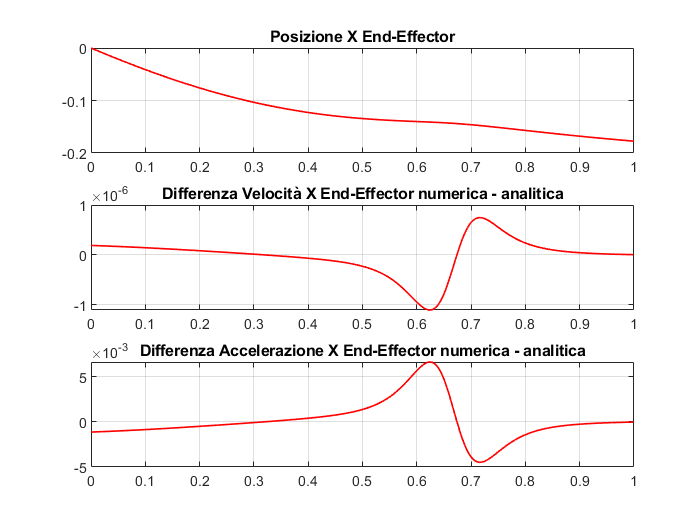

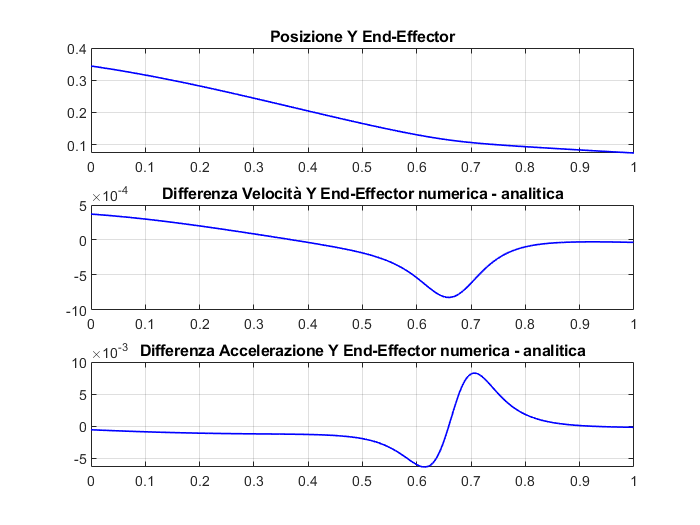

Plot_EF(PKM,P, P_p34, P_pp34, P_pM)

**Confronto cinematica matlab e adams**

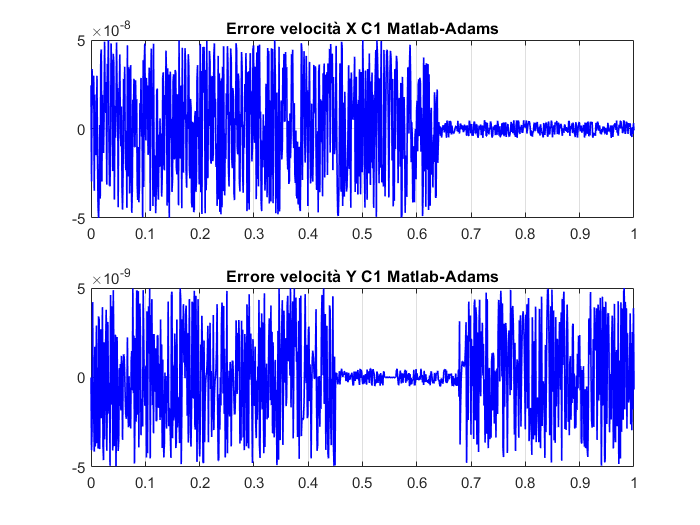

load PKM_PosEF
load PKM_VelEF
load PKM_AccEF
load PKM_PosE1
load PKM_VelE1
load PKM_AccE1
load PKM_Pa_VelCM
C1x_p_ad = PKM_Pa_VelCM(:,1);
C1x_p_ad = C1x_p_ad';
C1y_p_ad = PKM_Pa_VelCM(:,2);
C1y_p_ad = C1y_p_ad';
figure
subplot(2,1,1);
plot(time,C2_p(1,:)-C1x_p_ad,'color','b','linewidth',1)
title('Errore velocità X C1 Matlab-Adams')
grid on

subplot(2,1,2); 
plot(time,C2_p(2,:)-C1y_p_ad,'color','b','linewidth',1)
title('Errore velocità Y C1 Matlab-Adams')
grid on

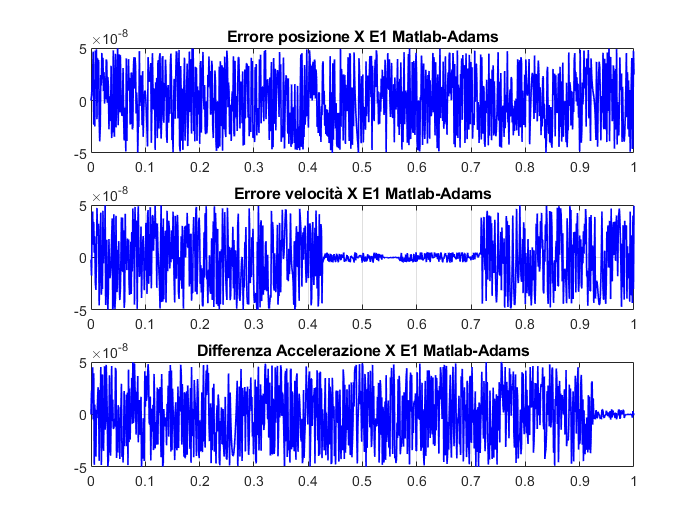

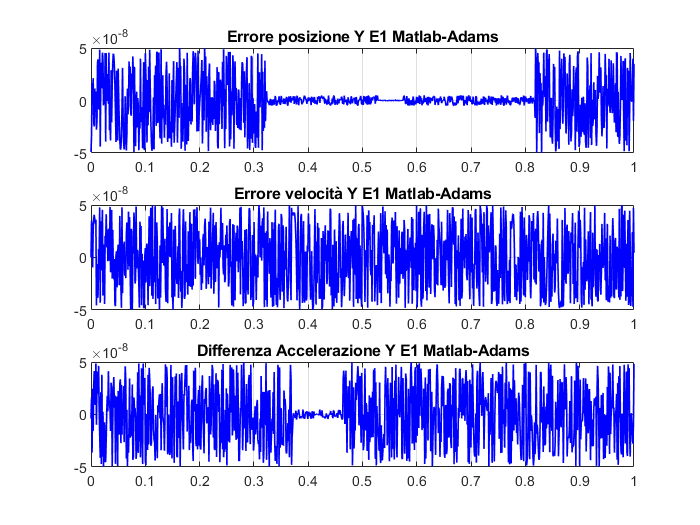

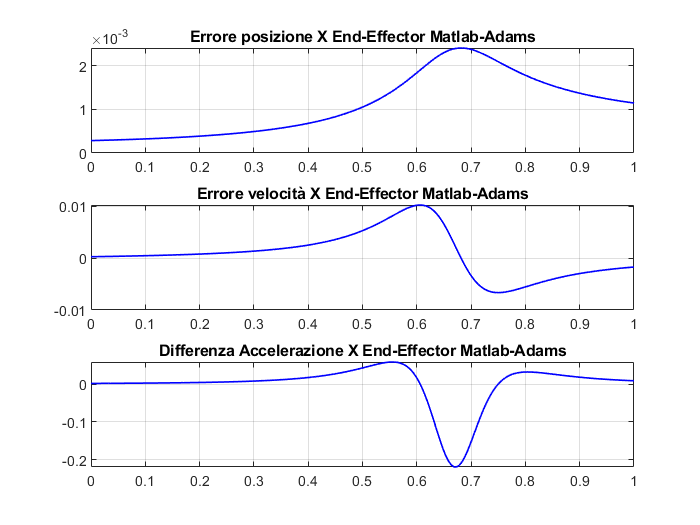

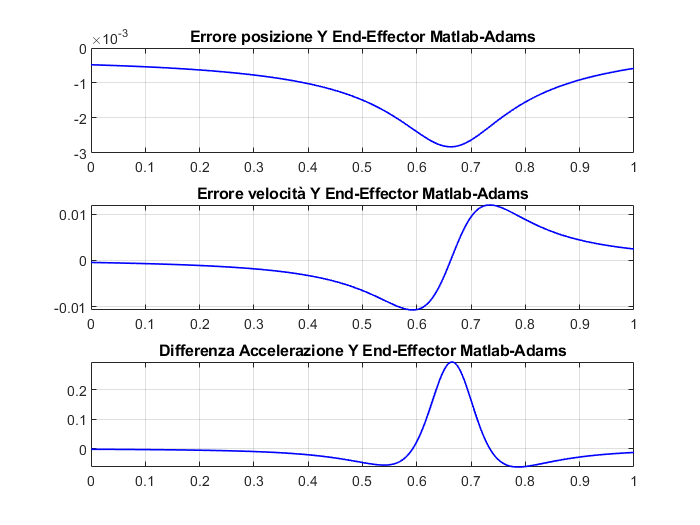

Matlab_Adams_Cinematica(PKM_PosEF, P, PKM_VelEF, P_p, PKM_AccEF, P_pp, PKM_PosE1, E1, PKM_VelE1, E1_p, PKM_AccE1, E1_pp)

## Cinematica Inversa

**Analisi di posizione**

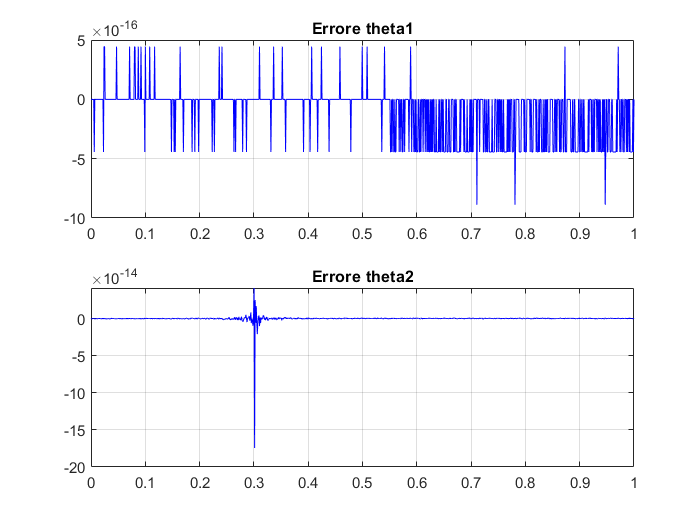

[theta1inv,theta2inv] = Cinematica_Inversa_Posizione(P, PKM, theta1ldm, theta2ldm);
Errore_theta1 = theta1ldm - theta1inv;
Errore_theta2 = theta2ldm - theta2inv;
time = linspace(0,PKM.ta,length(Theta_p));

figure
subplot(2,1,1);
plot(time,Errore_theta1,'color','b')
title('Errore theta1')
grid on
subplot(2,1,2); 
plot(time,Errore_theta2,'color','b')
title('Errore theta2')
grid on

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1inv,theta2inv,theta3,theta4)

**Analisi di velocità**

Theta_p_inv = Cinematica_Inversa_Velocita(J,P_p);

**Analisi di accelerazione**

% Theta_pp_inv = Cinematica_Inversa_Accelerazione(J_p,J,Theta_p,P_pp);

## Dinamica

**Metodo azioni vicolari**

[C1_AV, C2_AV] = Dinamica(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,theta3_p,theta4_p,...
    theta1ldm_pp,theta2ldm_pp,theta3_pp,theta4_pp,thetavldm_pp)

C1_AV =     0.3925    0.3918    0.3910    0.3902    0.3894    0.3887    0.3879    0.3871    0.3863    0.3855    0.3847    0.3840    0.3832    0.3824    0.3816    0.3808    0.3800    0.3792    0.3784    0.3776    0.3768    0.3760    0.3752    0.3745    0.3737    0.3729    0.3721    0.3712    0.3704    0.3696    0.3688    0.3680    0.3672    0.3664    0.3656    0.3648    0.3640    0.3632    0.3624    0.3615    0.3607    0.3599    0.3591    0.3583    0.3575    0.3566    0.3558    0.3550    0.3542    0.3533


C2_AV =    -0.7903   -0.7914   -0.7925   -0.7936   -0.7947   -0.7958   -0.7969   -0.7980   -0.7991   -0.8002   -0.8012   -0.8023   -0.8034   -0.8044   -0.8055   -0.8066   -0.8076   -0.8087   -0.8097   -0.8108   -0.8118   -0.8128   -0.8139   -0.8149   -0.8159   -0.8169   -0.8179   -0.8189   -0.8199   -0.8209   -0.8219   -0.8229   -0.8239   -0.8249   -0.8259   -0.8269   -0.8278   -0.8288   -0.8298   -0.8307   -0.8317   -0.8326   -0.8336   -0.8345   -0.8354   -0.8364   -0.8373   -0.8382   -0.8391   -0.8401


**Metodo PLV**

[C1_PLV, C2_PLV, M, K] = Dinamica_PLV(PKM,theta1ldm_p,theta2ldm_p,theta1ldm_pp,theta2ldm_pp,J1,J2,J3,J4,JE,J34,J1p,J2p,J3p,J4p,JEp,J34p)

C1_PLV =     0.3495    0.3488    0.3481    0.3473    0.3466    0.3459    0.3451    0.3444    0.3436    0.3429    0.3422    0.3414    0.3407    0.3399    0.3392    0.3384    0.3377    0.3369    0.3362    0.3354    0.3347    0.3339    0.3332    0.3324    0.3317    0.3309    0.3302    0.3294    0.3287    0.3279    0.3271    0.3264    0.3256    0.3248    0.3241    0.3233    0.3226    0.3218    0.3210    0.3203    0.3195    0.3187    0.3179    0.3172    0.3164    0.3156    0.3148    0.3141    0.3133    0.3125


C2_PLV =    -0.7028   -0.7038   -0.7048   -0.7058   -0.7068   -0.7078   -0.7088   -0.7098   -0.7108   -0.7118   -0.7127   -0.7137   -0.7147   -0.7157   -0.7166   -0.7176   -0.7185   -0.7195   -0.7204   -0.7214   -0.7223   -0.7233   -0.7242   -0.7251   -0.7261   -0.7270   -0.7279   -0.7288   -0.7297   -0.7307   -0.7316   -0.7325   -0.7334   -0.7343   -0.7351   -0.7360   -0.7369   -0.7378   -0.7387   -0.7395   -0.7404   -0.7413   -0.7421   -0.7430   -0.7438   -0.7447   -0.7455   -0.7464   -0.7472   -0.7481


M =     0.4345   -0.1215    0.4349   -0.1221    0.4354   -0.1227    0.4359   -0.1232    0.4363   -0.1238    0.4368   -0.1244    0.4373   -0.1250    0.4377   -0.1256    0.4382   -0.1262    0.4387   -0.1268    0.4392   -0.1274    0.4396   -0.1280    0.4401   -0.1286    0.4406   -0.1293    0.4411   -0.1299    0.4416   -0.1305    0.4420   -0.1311    0.4425   -0.1317    0.4430   -0.1323    0.4435   -0.1330    0.4440   -0.1336    0.4445   -0.1342    0.4449   -0.1348    0.4454   -0.1355    0.4459   -0.1361
   -0.1215    0.4345   -0.1221    0.4349   -0.1227    0.4354   -0.1232    0.4359   -0.1238    0.4364   -0.1244    0.4368   -0.1250    0.4373   -0.1256    0.4378   -0.1262    0.4383   -0.1268    0.4388   -0.1274    0.4393   -0.1280    0.4398   -0.1286    0.4403   -0.1293    0.4408   -0.1299    0.4413   -0.1305    0.4418   -0.1311    0.4423   -0.1317    0.4428   -0.1323    0.4433   -0.1330    0.4438   -0.1336    0.4444   -0.1342    0.4449   -0.1348    0.4454   -0.1355    0.4459   -0.1361    0

K =     0.2329   -0.1163    0.2334   -0.1172    0.2338   -0.1180    0.2342   -0.1188    0.2346   -0.1197    0.2351   -0.1205    0.2355   -0.1214    0.2360   -0.1223    0.2364   -0.1231    0.2369   -0.1240    0.2373   -0.1249    0.2378   -0.1258    0.2382   -0.1267    0.2387   -0.1276    0.2391   -0.1285    0.2396   -0.1294    0.2401   -0.1304    0.2406   -0.1313    0.2410   -0.1322    0.2415   -0.1332    0.2420   -0.1341    0.2425   -0.1351    0.2430   -0.1361    0.2435   -0.1371    0.2440   -0.1380
   -0.4684    0.2341   -0.4695    0.2353   -0.4705    0.2366   -0.4715    0.2379   -0.4726    0.2391   -0.4736    0.2404   -0.4747    0.2417   -0.4758    0.2430   -0.4768    0.2443   -0.4779    0.2456   -0.4789    0.2470   -0.4800    0.2483   -0.4811    0.2496   -0.4822    0.2510   -0.4832    0.2523   -0.4843    0.2537   -0.4854    0.2551   -0.4865    0.2564   -0.4876    0.2578   -0.4887    0.2592   -0.4898    0.2606   -0.4909    0.2620   -0.4920    0.2634   -0.4931    0.2648   -0.4942    0

**Confronto tra i due metodi**

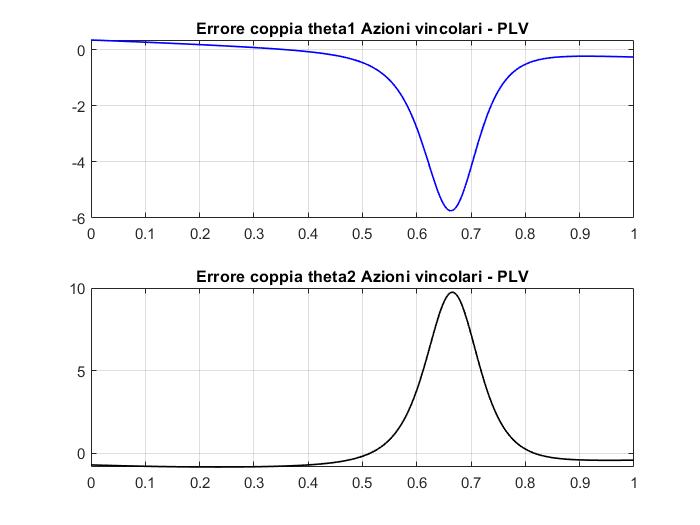

ErrC1 = C1_PLV(1,:)-C1_AV(1,:);
ErrC2 = C2_PLV(1,:)-C2_AV(1,:);
figure
subplot(2,1,1);
plot(time(1,:),C1_PLV(1,:),'color','b','linewidth',1)
title('Errore coppia theta1 Azioni vincolari - PLV')
grid on
subplot(2,1,2);
plot(time(1,:),C2_PLV(1,:),'color','k','linewidth',1)
title('Errore coppia theta2 Azioni vincolari - PLV')
grid on

**Confronto dinamica Matlab-Adams**

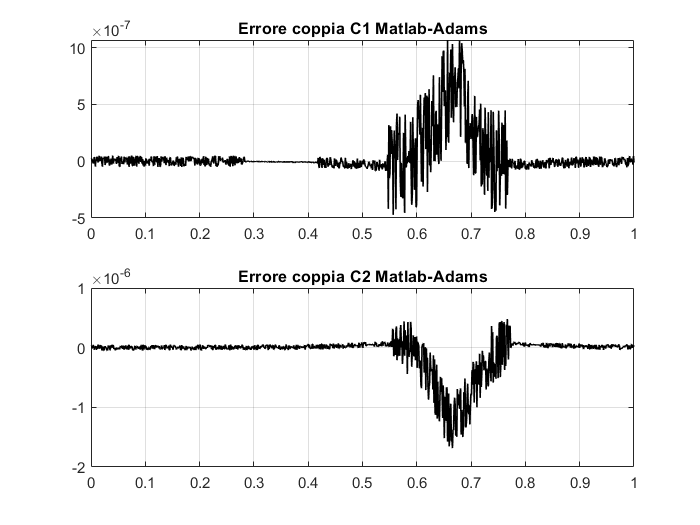

load PKM_Pa_CoppieNOEF
Matlab_Adams_Dinamica(PKM_Pa_CoppieNOEF, -C1_PLV, -C2_PLV)